# Compare HDR versus Burst

experiment with various HDR and other multi-image "burst" algorithms for capturing scenes with a variety of dynamic ranges, as well as object and camera motion.

## Create a pbrt scene we can use

Using pbrt lets us get the highest-fidelity rendering

ieInit();
sceneLuminance = 200

sceneLuminance = 200

numRays = 256

numRays = 256

filmResolution = 256

filmResolution = 256

pbrtLensFile = false

pbrtLensFile = logical
   0


sceneChoice = "CornellBoxReference"

sceneChoice = "CornellBoxReference"

apertureDiameter = 6% in mm

apertureDiameter = 6

if strcmp(sceneChoice, "Cornell Box with Bunny")
    scenePath = 'Cornell_BoxBunnyChart';        
    sceneName = 'cornell box bunny chart';
elseif strcmp(sceneChoice, "CornellBoxReference")
    scenePath = "CornellBoxReference";
    sceneName = "CornellBoxReference";
else
    scenePath = 'ChessSet';
    sceneName = 'chessSet';
end

if pbrtLensFile
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance, ...
    'lensFile','dgauss.22deg.6.0mm.json',...
    'apertureDiameter', apertureDiameter);
else
    pbrtCPScene = cpScene('pbrt', 'scenePath', scenePath, 'sceneName', sceneName, ...
    'resolution', [filmResolution filmResolution], ...
    'numRays', numRays, 'sceneLuminance', sceneLuminance);
end

Read 9 materials
Reading C4D geometry information.


## Create our sample camera

Just one module

% some timing code, just to see how fast we run...
setpref('ISET', 'benchmarkstart', cputime); 
setpref('ISET', 'tStart', tic);

% cpBurstCamera is a sub-class of cpCamera that implements simple HDR and Burst
% capture and processing
ourCamera = cpBurstCamera(); 

% We'll use a pre-defined sensor for our Camera Module, and let it use
% default optics for now. We can then assign the module to our camera:
sensor = sensorFromFile('ar0132atSensorRGB'); 
% Cameras can eventually have more than one module (lens + sensor)
% but for now, we just create one using our sensor
ourCamera.cmodules(1) = cpCModule('sensor', sensor); % default

## Let's Look at the Camera we've Created

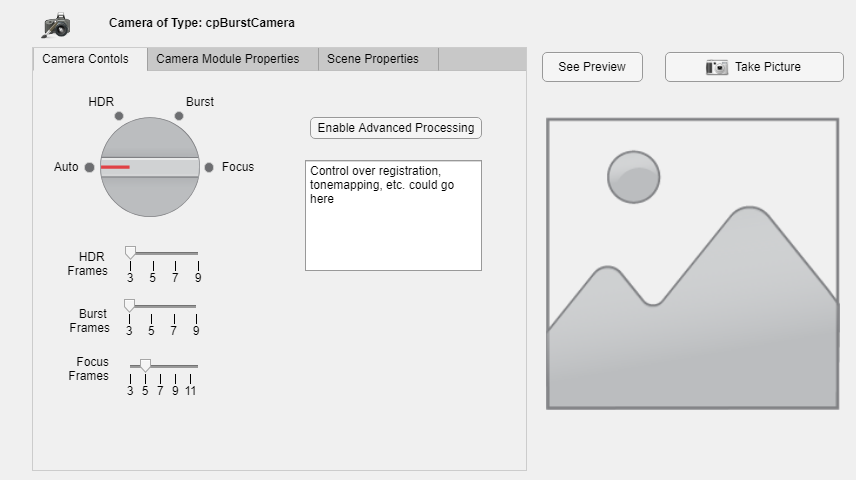

cpCameraWindow(ourCamera, pbrtCPScene);

## Take Pictures using Auto, HDR, and Burst Intents

For the simplest case we ask our camera to take some pictures using pre-defined intents. By deault our camera assumes the 'Auto' intent. We also demonstrate 'Burst', which will capture more frames if the camera type we are using supports it. 'HDR' also fires a burst, but bracketed. Our default camera sums the frames in Burst mode, and chooses the highest non-saturated value at each pixel for HDR mode.

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp0a21f927_13dd_43f0_b4ce_f7f7a3dbb192
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp0a21f927_13dd_43f0_b4ce_f7f7a3dbb192 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp0a21f927_13dd_43f0_b4ce_f7f7a3dbb192\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp0a21f927_13dd_43f0_b4ce_f7f7a3dbb192\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp0a21f927_13dd_43f0_b4ce_f7f7a3dbb192 -v C:/iset/iset3d/local/CornellBoxReference/tp0a21f927_13dd_43f0_b4ce_f7f7a3dbb192:/tp0a21f927_13dd_43f0_b4ce_f7f7a3dbb192 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp0a523230_ce16_4e1b_864e_3532972f452f
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp0a523230_ce16_4e1b_864e_3532972f452f 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp0a523230_ce16_4e1b_864e_3532972f452f\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp0a523230_ce16_4e1b_864e_3532972f452f\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp0a523230_ce16_4e1b_864e_3532972f452f -v C:/iset/iset3d/local/CornellBoxReference/tp0a523230_ce16_4e1b_864e_3532972f452f:/tp0a523230_ce16_4e1b_864e_3532972f452f vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

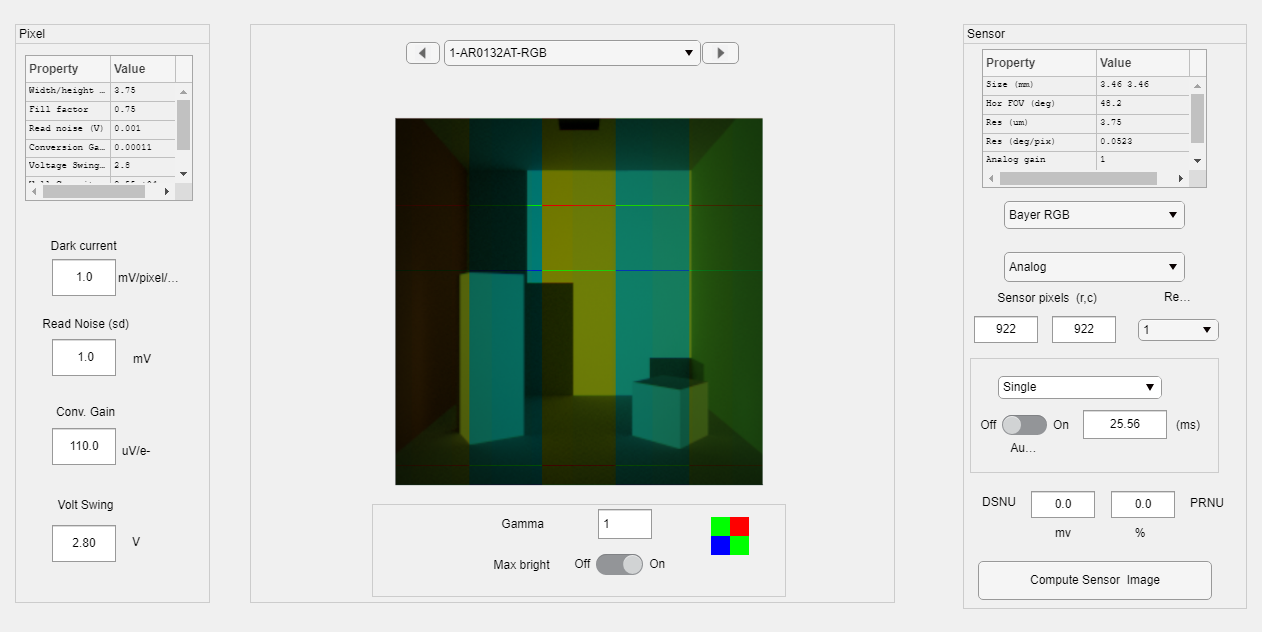

autoImage = ourCamera.TakePicture(pbrtCPScene, 'Auto',...
    'imageName','Auto Mode no motion', 'insensorIP',false); 

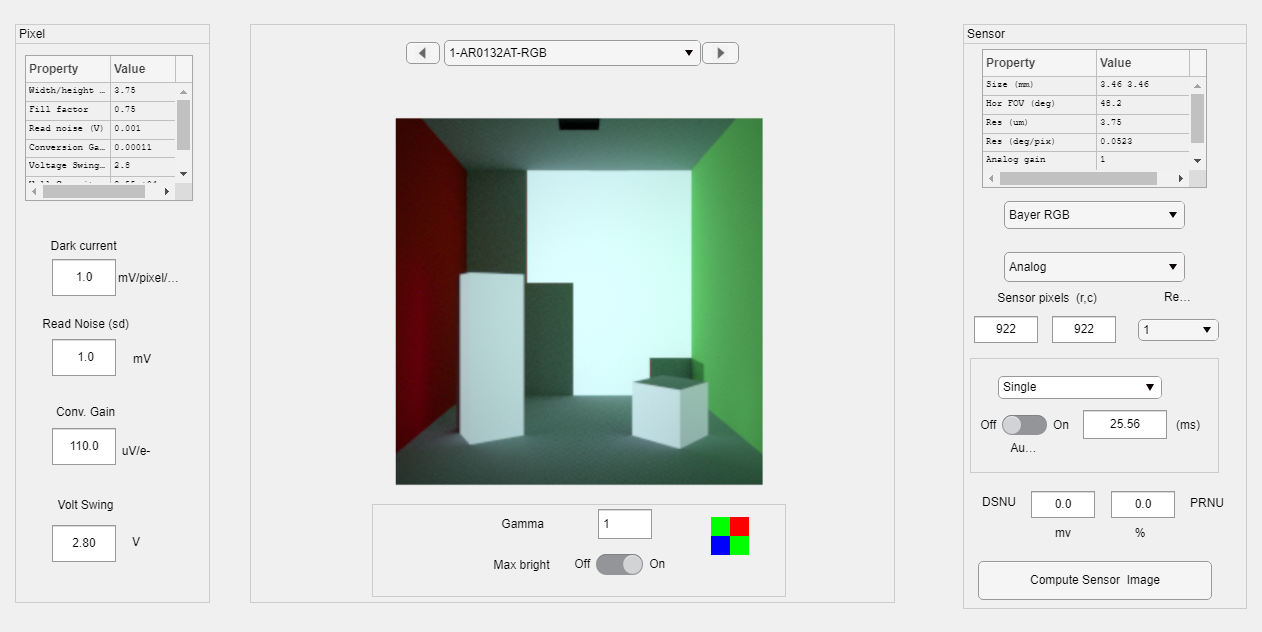

imshow(autoImage);

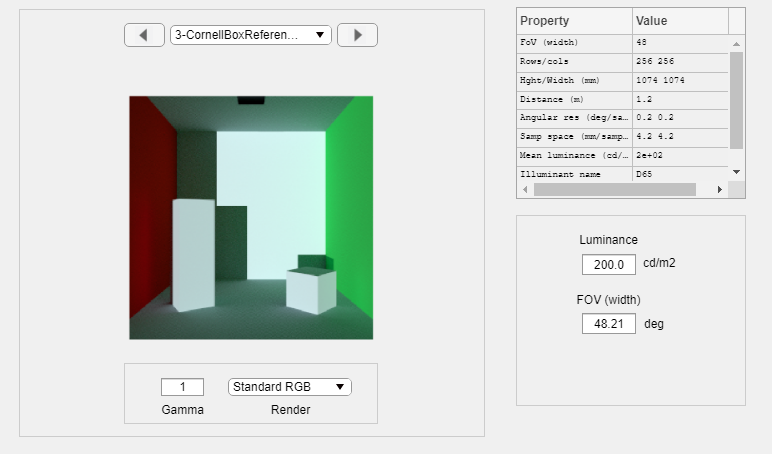

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp968f7f90_1642_4f50_8e57_11823214efd2
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp968f7f90_1642_4f50_8e57_11823214efd2 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp968f7f90_1642_4f50_8e57_11823214efd2\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp968f7f90_1642_4f50_8e57_11823214efd2\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp968f7f90_1642_4f50_8e57_11823214efd2 -v C:/iset/iset3d/local/CornellBoxReference/tp968f7f90_1642_4f50_8e57_11823214efd2:/tp968f7f90_1642_4f50_8e57_11823214efd2 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp7149c86d_cfa2_4432_88c0_b02966d137a3
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp7149c86d_cfa2_4432_88c0_b02966d137a3 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp7149c86d_cfa2_4432_88c0_b02966d137a3\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp7149c86d_cfa2_4432_88c0_b02966d137a3\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp7149c86d_cfa2_4432_88c0_b02966d137a3 -v C:/iset/iset3d/local/CornellBoxReference/tp7149c86d_cfa2_4432_88c0_b02966d137a3:/tp7149c86d_cfa2_4432_88c0_b02966d137a3 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpa8bf5e53_d475_451b_9a5f_6f9a4c72c748
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpa8bf5e53_d475_451b_9a5f_6f9a4c72c748 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpa8bf5e53_d475_451b_9a5f_6f9a4c72c748\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpa8bf5e53_d475_451b_9a5f_6f9a4c72c748\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpa8bf5e53_d475_451b_9a5f_6f9a4c72c748 -v C:/iset/iset3d/local/CornellBoxReference/tpa8bf5e53_d475_451b_9a5f_6f9a4c72c748:/tpa8bf5e53_d475_451b_9a5f_6f9a4c72c748 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpae425edf_decd_4315_8d3d_e4798c979fb9
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpae425edf_decd_4315_8d3d_e4798c979fb9 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpae425edf_decd_4315_8d3d_e4798c979fb9\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpae425edf_decd_4315_8d3d_e4798c979fb9\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpae425edf_decd_4315_8d3d_e4798c979fb9 -v C:/iset/iset3d/local/CornellBoxReference/tpae425edf_decd_4315_8d3d_e4798c979fb9:/tpae425edf_decd_4315_8d3d_e4798c979fb9 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"


hdrSensorImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in sensor no motion', ...
    'insensorIP', true);

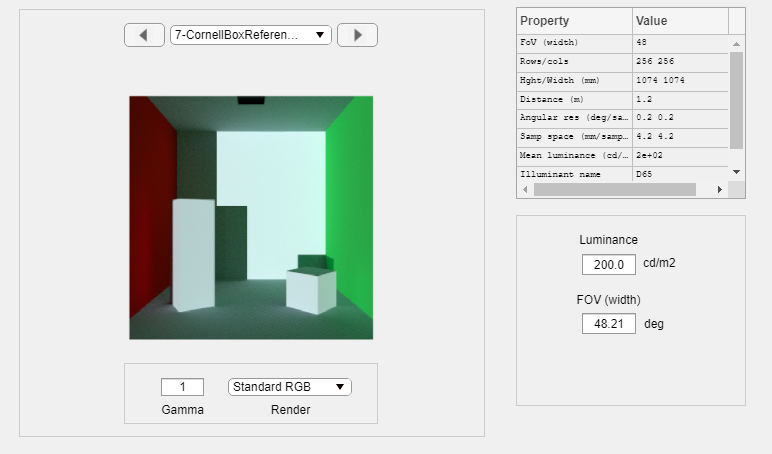

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpde323771_9c31_48bd_ad4a_882a7eb8fb41
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpde323771_9c31_48bd_ad4a_882a7eb8fb41 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpde323771_9c31_48bd_ad4a_882a7eb8fb41\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpde323771_9c31_48bd_ad4a_882a7eb8fb41\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpde323771_9c31_48bd_ad4a_882a7eb8fb41 -v C:/iset/iset3d/local/CornellBoxReference/tpde323771_9c31_48bd_ad4a_882a7eb8fb41:/tpde323771_9c31_48bd_ad4a_882a7eb8fb41 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpf54d5df6_1670_4f71_9561_4aa082883191
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpf54d5df6_1670_4f71_9561_4aa082883191 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpf54d5df6_1670_4f71_9561_4aa082883191\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpf54d5df6_1670_4f71_9561_4aa082883191\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpf54d5df6_1670_4f71_9561_4aa082883191 -v C:/iset/iset3d/local/CornellBoxReference/tpf54d5df6_1670_4f71_9561_4aa082883191:/tpf54d5df6_1670_4f71_9561_4aa082883191 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp119d865f_bf5b_46aa_bb06_6168370156bf
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp119d865f_bf5b_46aa_bb06_6168370156bf 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp119d865f_bf5b_46aa_bb06_6168370156bf\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp119d865f_bf5b_46aa_bb06_6168370156bf\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp119d865f_bf5b_46aa_bb06_6168370156bf -v C:/iset/iset3d/local/CornellBoxReference/tp119d865f_bf5b_46aa_bb06_6168370156bf:/tp119d865f_bf5b_46aa_bb06_6168370156bf vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp4285e740_73b6_40e2_8526_847926d1a18e
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp4285e740_73b6_40e2_8526_847926d1a18e 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp4285e740_73b6_40e2_8526_847926d1a18e\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp4285e740_73b6_40e2_8526_847926d1a18e\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp4285e740_73b6_40e2_8526_847926d1a18e -v C:/iset/iset3d/local/CornellBoxReference/tp4285e740_73b6_40e2_8526_847926d1a18e:/tp4285e740_73b6_40e2_8526_847926d1a18e vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

ipWindow(hdrSensorImage);

burstSensorImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in Sensor',...
    'insensorIP',true);

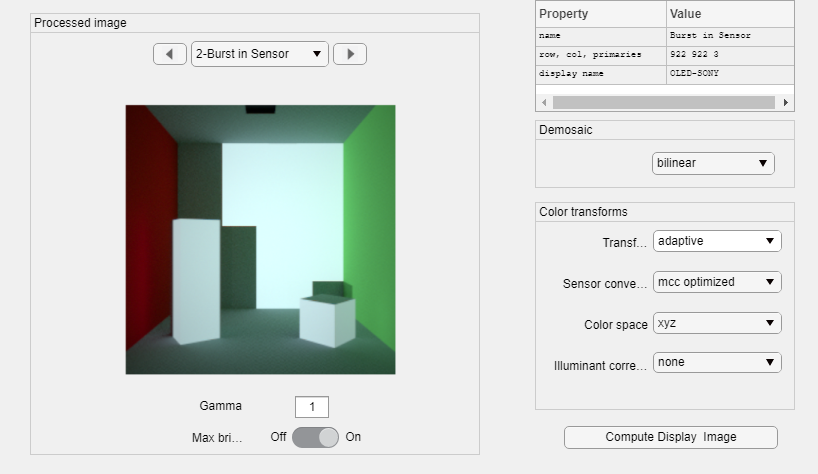

ipWindow(burstSensorImage);

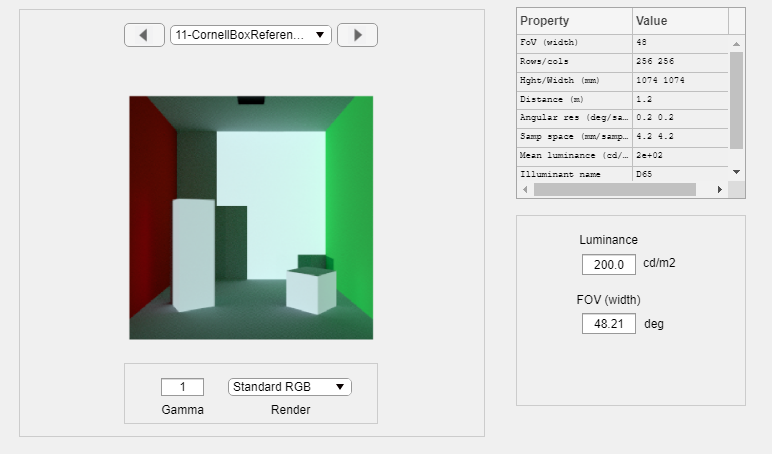

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp4b67286e_95db_4dde_be7f_cfa285b3ca6d
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp4b67286e_95db_4dde_be7f_cfa285b3ca6d 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp4b67286e_95db_4dde_be7f_cfa285b3ca6d\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp4b67286e_95db_4dde_be7f_cfa285b3ca6d\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp4b67286e_95db_4dde_be7f_cfa285b3ca6d -v C:/iset/iset3d/local/CornellBoxReference/tp4b67286e_95db_4dde_be7f_cfa285b3ca6d:/tp4b67286e_95db_4dde_be7f_cfa285b3ca6d vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp44672ea2_b3c8_4a27_ab56_60fe183c7916
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp44672ea2_b3c8_4a27_ab56_60fe183c7916 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp44672ea2_b3c8_4a27_ab56_60fe183c7916\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp44672ea2_b3c8_4a27_ab56_60fe183c7916\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp44672ea2_b3c8_4a27_ab56_60fe183c7916 -v C:/iset/iset3d/local/CornellBoxReference/tp44672ea2_b3c8_4a27_ab56_60fe183c7916:/tp44672ea2_b3c8_4a27_ab56_60fe183c7916 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpe0256ac0_7db5_49a1_b5ec_379048e7bb1c
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpe0256ac0_7db5_49a1_b5ec_379048e7bb1c 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpe0256ac0_7db5_49a1_b5ec_379048e7bb1c\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpe0256ac0_7db5_49a1_b5ec_379048e7bb1c\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpe0256ac0_7db5_49a1_b5ec_379048e7bb1c -v C:/iset/iset3d/local/CornellBoxReference/tpe0256ac0_7db5_49a1_b5ec_379048e7bb1c:/tpe0256ac0_7db5_49a1_b5ec_379048e7bb1c vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp839532fc_669b_4ec3_b5a3_b274c3c12e22
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp839532fc_669b_4ec3_b5a3_b274c3c12e22 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp839532fc_669b_4ec3_b5a3_b274c3c12e22\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp839532fc_669b_4ec3_b5a3_b274c3c12e22\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp839532fc_669b_4ec3_b5a3_b274c3c12e22 -v C:/iset/iset3d/local/CornellBoxReference/tp839532fc_669b_4ec3_b5a3_b274c3c12e22:/tp839532fc_669b_4ec3_b5a3_b274c3c12e22 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"


pbrtCPScene.cameraMotion = {{'unused', [.002, 0, 0], [0, 0, 0]}};
hdrMotionImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in ISP with Motion', ...
    'insensorIP', true);

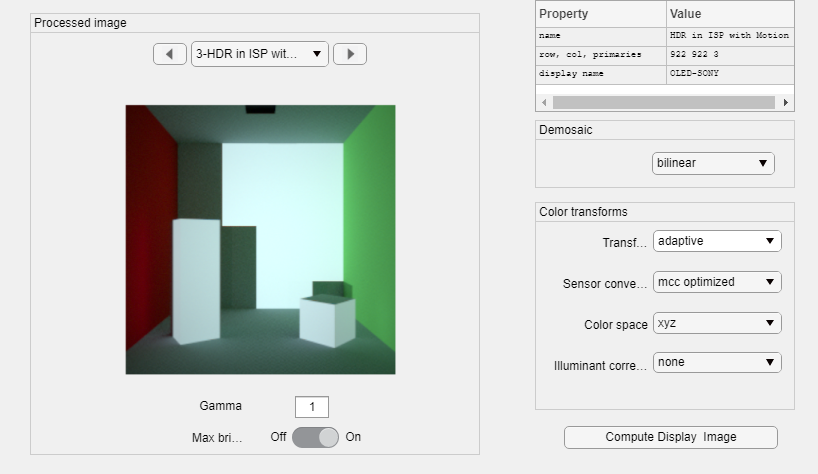

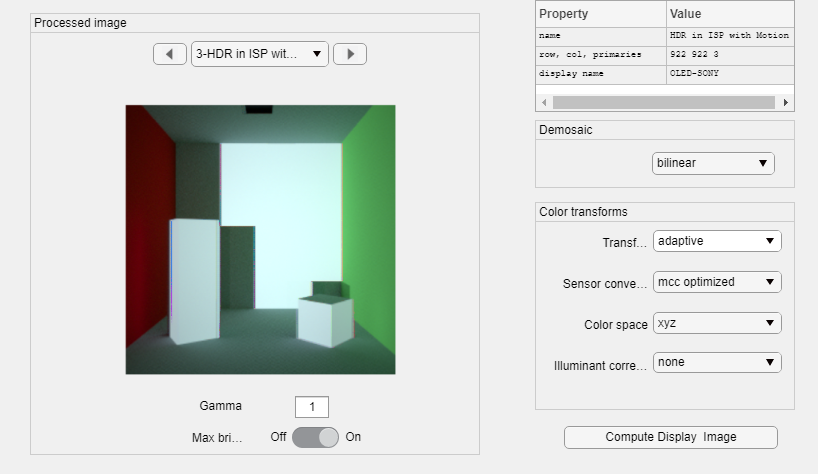

if isstruct(hdrMotionImage)
    ipWindow(hdrMotionImage);
else
    imshow(hdrMotionImage);
    imshowpair(hdrImage,hdrMotionImage, 'montage');
end

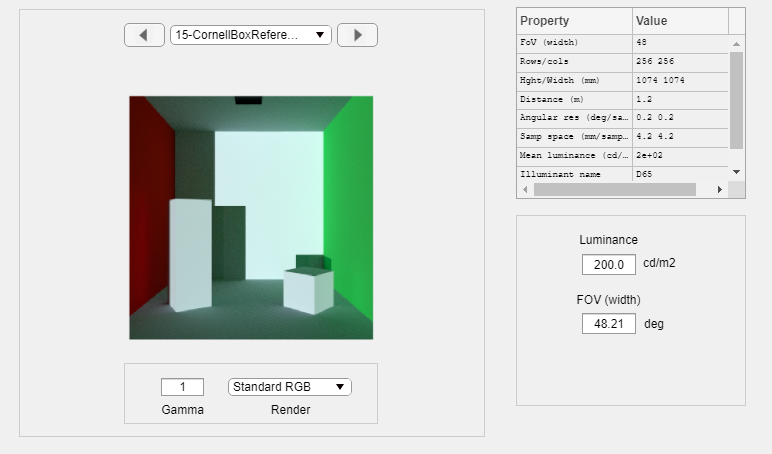

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpdc7d41c8_327b_4d5c_9f7b_12e651a3f353
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpdc7d41c8_327b_4d5c_9f7b_12e651a3f353 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpdc7d41c8_327b_4d5c_9f7b_12e651a3f353\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpdc7d41c8_327b_4d5c_9f7b_12e651a3f353\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpdc7d41c8_327b_4d5c_9f7b_12e651a3f353 -v C:/iset/iset3d/local/CornellBoxReference/tpdc7d41c8_327b_4d5c_9f7b_12e651a3f353:/tpdc7d41c8_327b_4d5c_9f7b_12e651a3f353 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

New light added.
Creating output folder C:\iset\iset3d\local\CornellBoxReference\tpcdc1387c_738e_4d03_a5db_5a50555342d6
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tpcdc1387c_738e_4d03_a5db_5a50555342d6 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpcdc1387c_738e_4d03_a5db_5a50555342d6\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tpcdc1387c_738e_4d03_a5db_5a50555342d6\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tpcdc1387c_738e_4d03_a5db_5a50555342d6 -v C:/iset/iset3d/local/CornellBoxReference/tpcdc1387c_738e_4d03_a5db_5a50555342d6:/tpcdc1387c_738e_4d03_a5db_5a50555342d6 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/C

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp41b2d891_166b_4198_ac7a_741bc1a8a873
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp41b2d891_166b_4198_ac7a_741bc1a8a873 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp41b2d891_166b_4198_ac7a_741bc1a8a873\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp41b2d891_166b_4198_ac7a_741bc1a8a873\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp41b2d891_166b_4198_ac7a_741bc1a8a873 -v C:/iset/iset3d/local/CornellBoxReference/tp41b2d891_166b_4198_ac7a_741bc1a8a873:/tp41b2d891_166b_4198_ac7a_741bc1a8a873 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

ans = "Scene luminance is: 200.000000"

Creating output folder C:\iset\iset3d\local\CornellBoxReference\tp4b9e598b_6939_429e_884b_91099f0e71e5
Copied resources from:
C:\iset\iset3d\data\V3\CornellBoxReference 
to 
C:\iset\iset3d\local\CornellBoxReference\tp4b9e598b_6939_429e_884b_91099f0e71e5 
 
Material file CornellBoxReference_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp4b9e598b_6939_429e_884b_91099f0e71e5\CornellBoxReference_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Material file CornellBoxReference_depth_materials.pbrt written successfully.
C:\iset\iset3d\local\CornellBoxReference\tp4b9e598b_6939_429e_884b_91099f0e71e5\CornellBoxReference_depth_geometry.pbrt is written out 
Docker command
	docker run -ti --rm -w /tp4b9e598b_6939_429e_884b_91099f0e71e5 -v C:/iset/iset3d/local/CornellBoxReference/tp4b9e598b_6939_429e_884b_91099f0e71e5:/tp4b9e598b_6939_429e_884b_91099f0e71e5 vistalab/pbrt-v3-spectral:latest pbrt --outfile renderings/CornellBoxReferenc

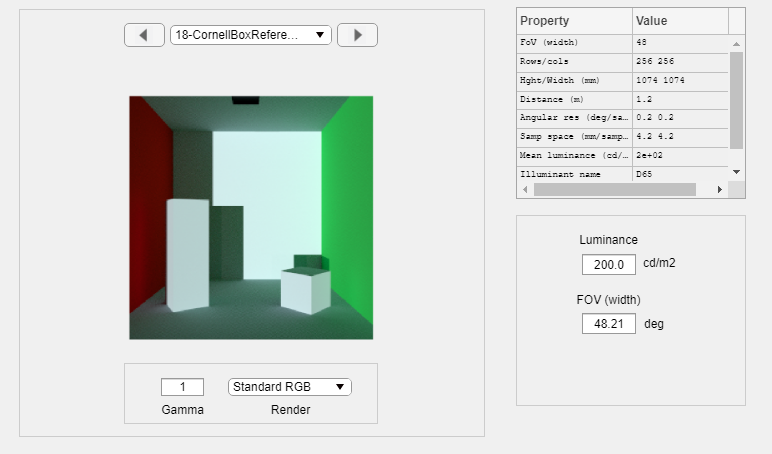

ans = "Scene luminance is: 200.000000"


% Now try with firmware ISP
hdrISPMotionImage = ourCamera.TakePicture(pbrtCPScene, 'HDR',...
    'numHDRFrames', 3,'imageName','HDR in ISP with Motion', ...
    'insensorIP', false);

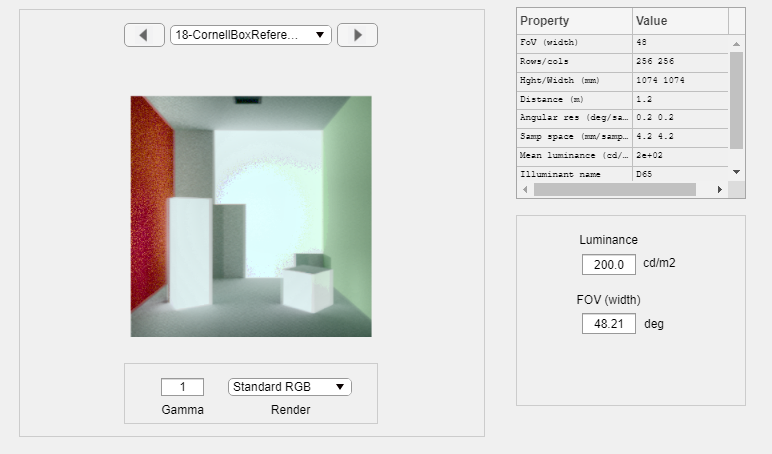

Unrecognized function or variable 'hdrImage'.

if isstruct(hdrISPMotionImage)
    ipWindow(hdrISPMotionImage);
else
    imshow(hdrISPMotionImage);
    imshowpair(hdrMotionImage,hdrISPMotionImage, 'montage');
end


burstMotionImage = ourCamera.TakePicture(pbrtCPScene, 'Burst',...
    'numBurstFrames', 3, 'imageName','Burst in ISP with Motion',...
    'insensorIP',false);
imshowpair(hdrMotionImage,burstMotionImage,'montage');
